### Load in pre-prepared network

% clear; close all
% load BigNetworkExperimentsBetaSkeleton.mat

### Building the node constraints

The number of routes from node 1 to 100 is erm rather large. So we definitely aren't going to compute them all and so route variables (flows) is not the way to go here. 

% paths=allpaths(G,oNode,dNode);  
% don't execute this code unless you want
% your computer to hang

You could of course compute an assignment using just a small subset of the available routes - and that is what you need to do in SUE problems - but here, for classical UE, a tractable approach is instead to use the link-based formulation and the Beckmann functional, which will lead to a quadratic programme with linear constraints. The SO problem is very similar, with just a slight change to the function that must be minimised.

There are numEdge links and therefore the link flow vector $\mathbf{x}$ that we try to solve for is of length numEdge. The node constraints are $\mathbf{B}\mathbf{x}=\mathbf{s}$, as explained in lectures, and we need to formulate the $\mathbf{B}$ and the $\mathbf{s}$. 

In fact, $\mathbf{s}$ is rather easy.

s = zeros(numNode,1);
dNode = 1000; % oh eddie boy that was wrong
s(oNode)=1;
s(dNode)=-1;

This expresses that for most nodes, the corresponding element of $\mathbf{s}$ is zero, ie traffic is conserved, whereas at O it is generated at rate 1 and at D it is absorbed at rate 1. We can then scale $\mathbf{s}$ by a scalar demand parameter $d$ a bit later on.

The matrix $\mathbf{B}$ is then built up node by node by considering which edges point out (+1) and point in (-1). To be honest, it doesn't matter which way round you do the signs provided you correct $\mathbf{s}$ accordingly.

B=zeros(numNode,numEdge);
listEdge = (1:numEdge)';
sNode = G.Edges.EndNodes(:,1);
tNode = G.Edges.EndNodes(:,2);
isCleverMethod= true;
if isCleverMethod
% I think there is a vectorised way of doing this if only I were clever
    B(sub2ind(size(B), sNode, listEdge)) = 1;   % Set +1 for the start nodes
    B(sub2ind(size(B), tNode, listEdge)) = -1;  % Set -1 for the end nod
% else % do it ponderously with a loop
%     for i=1:numEdge
%         B(sNode(i),listEdge(i))=1;
%         B(tNode(i),listEdge(i))=-1;
%     end
end

### Constructing the objective and running the quadratic programme

Take a look at help page for quadprog - we will use the form

 X = quadprog(H,f,A,b,Aeq,beq,LB,UB)

First the constraints

d=1; % demand
Aeq=B;     % node conservation matrix
beq=d*s;   % node conservation vector
A=[];      % no inequality constraints
bvec=[];      % no inequality constraints - note avoiding name conflict with my existing b
LB = zeros(numEdge,1); % set a lower bound of zero for all of the link flows.
UB=[]; % no upper bounds for the link flows - although you could use this facility to set
% a capacity (ie max flow) for each link

Now set up the objective function

H=diag(b); % the square matrix with the elements of b on its diagonal.
% Note this is what is needed for the Beckmann functional, because of the
% way matlab inserts a factor of 1/2 in front of the quadratic form.
% If we were doing SO, there would need to be a factor of 2 in here.

f=a; % the linear part of the quadratic form

To Do List

- Show graphically how the network ‘fills up’ as demand d is increased from 0 over an appropriate range that you should choose. -> I would like to print the number of unused nodes and I would like to make this into an animation but it is good enough for now

- You should certainly ensure that the peak Price of Anarchy (PoA) is captured — and this may require you to also compute the System Optimal (SO) assignment. 

- Finally, for the UE assignment with a fixed value of d that you should choose, demonstrate that there are multiple routes with the same total cost.

- calculate the peak price of anarchy (and show this graphically). for each graph find the calculate the SO, the UE, the PoA, print PoA next to graph

- pick a fixed value of d and show that multiple routes have the same total cost

% Parameters
dValues = 0.1:0.1:5;         % Demand levels from 0 to 100 in steps of 20
numSteps = length(dValues); % Number of demand steps

% Preallocate space for storing link flows
linkFlows = zeros(numEdge, numSteps, 2); % extra dimension to store UE vs SO

% Set up the optimization problem
Aeq = B;                % Node conservation matrix
A = [];                 % No inequality constraints
bvec = [];              % No inequality constraints
LB = zeros(numEdge, 1); % Lower bound for link flows
UB = [];                % No upper bounds

H = diag(b);            % Quadratic term for the Beckmann functional
f = a;

% finding UE and SO values for each demand plot side by side
% intialising storage arrays for System Cost Value and PoA
PoA_arr = zeros(numSteps, 1);
Sys_Cost = zeros(numSteps,2);

% Loop through each demand value
tic
for i = 1:numSteps
    d = dValues(i);
    beq = d * s;        % Scale the demand vector
    [x_UE, f_UE, ef_UE, x_SO, f_SO, ef_SO, PoA] = Price_of_Anarchy(H, f, A, bvec, Aeq, beq, LB, UB);
    % Store the link flows
    linkFlows(:, i, 1) = x_UE;
    linkFlows(:, i, 2) = x_SO;

    % store system costs and PoA
    Sys_Cost(i,:) = [f_UE, f_SO];
    PoA_arr(i) = PoA;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

toc

Elapsed time is 293.448323 seconds.


% can make this faster with arrayfun

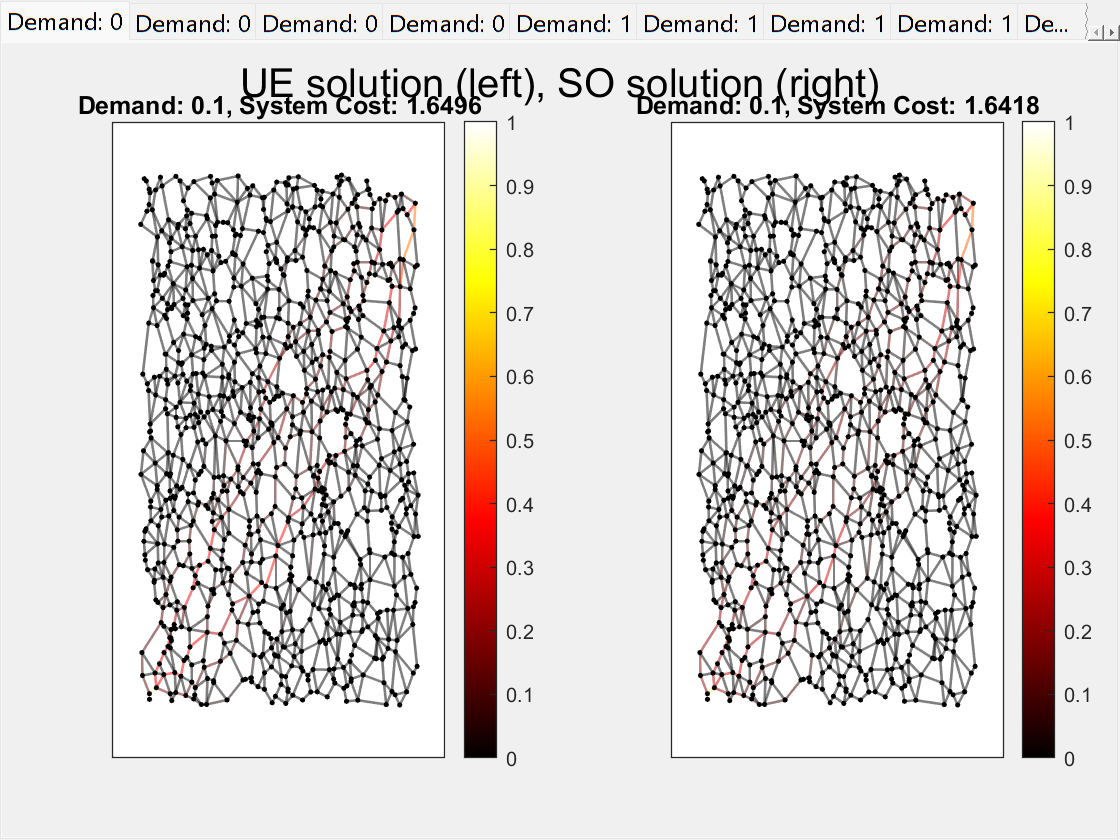

% Plot the networks
% intialising figures for plotting
% Create a main figure
mainFig = figure('Name', 'UE vs SO', 'NumberTitle', 'off');

% Create a tab group
tabGroup = uitabgroup(mainFig);

% Number of tabs
numTabs = numSteps;

% Array to store axes handles
axesArray = cell(numTabs, 2); % Each tab has 2 subplots

for i = 1:numSteps
    tab = uitab(tabGroup, 'Title', sprintf('Demand: %d', round(dValues(i))));
    % Create subplots in the tab
    for sp = 1:2
        % Create an axes for the subplot in the current tab
        axesArray{i, sp} = axes('Parent', tab, 'Position', [0.1 + 0.5*(sp-1), 0.1, 0.4, 0.8]);
        
        % Plot example data
        % plot(axesArray{t, sp}, rand(1, 10)); % Random data
        % title(axesArray{t, sp}, sprintf('Tab %d, Subplot %d', t, sp));
        plotNetwork(G, linkFlows(:,i,sp), nodeCoordinates, axesArray{i, sp});  % Custom function to visualize the network
        title(['Demand: ', num2str(dValues(i)), ', System Cost: ', num2str(Sys_Cost(i,sp))]);
    end
    sgtitle('UE solution (left), SO solution (right)') 
end

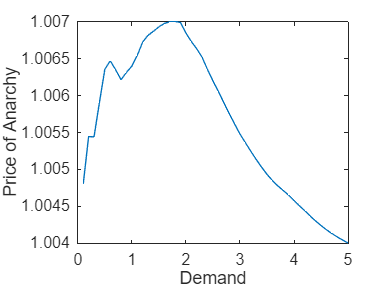

% plot PoA
figure()
plot(dValues, PoA_arr)
% title("Price of Anarchy")
xlabel("Demand")
ylabel("Price of Anarchy")